clear all;
clc;

Data_005Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour005.dat');
Data_010Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour010.dat');
Data_015Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour015.dat');
Data_020Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour020.dat');
Data_025Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour025.dat');
Data_030Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour030.dat');
Data_035Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour035.dat');
Data_040Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour040.dat');
Data_045Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour045.dat');
Data_050Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour050.dat');
Data_055Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour055.dat');
Data_060Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour060.dat');
Data_065Sec_dunham = readtable('Benchmark_Data_dunham\Contour_Plot_Data\Contour065.dat');

Results_005Sec = readtable('dats\Out0001.dat');
Results_010Sec = readtable('dats\Out0002.dat');
Results_015Sec = readtable('dats\Out0003.dat');
Results_020Sec = readtable('dats\Out0004.dat');
Results_025Sec = readtable('dats\Out0005.dat');
Results_030Sec = readtable('dats\Out0006.dat');
Results_035Sec = readtable('dats\Out0007.dat');
Results_040Sec = readtable('dats\Out0008.dat');
Results_045Sec = readtable('dats\Out0009.dat');
Results_050Sec = readtable('dats\Out0010.dat');
Results_055Sec = readtable('dats\Out0011.dat');
Results_060Sec = readtable('dats\Out0012.dat');
Results_065Sec = readtable('dats\Out0013.dat');
Results_070Sec = readtable('dats\Out0014.dat');
Results_075Sec = readtable('dats\Out0015.dat');

figure(1);
h1 = plot3(Data_010Sec_dunham.x1/1000,Data_010Sec_dunham.x3/1000,Data_010Sec_dunham.slip,'ko',"MarkerSize",2)

h1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 2
    MarkerFaceColor: 'none'
              XData: [1×338 double]
              YData: [1×338 double]
              ZData: [1×338 double]

  Show all properties


hold on
plot3(Data_020Sec_dunham.x1/1000,Data_020Sec_dunham.x3/1000,Data_020Sec_dunham.slip,'ko',"MarkerSize",2)
plot3(Data_030Sec_dunham.x1/1000,Data_030Sec_dunham.x3/1000,Data_030Sec_dunham.slip,'ko',"MarkerSize",2)
plot3(Data_040Sec_dunham.x1/1000,Data_040Sec_dunham.x3/1000,Data_040Sec_dunham.slip,'ko',"MarkerSize",2)
plot3(Data_050Sec_dunham.x1/1000,Data_050Sec_dunham.x3/1000,Data_050Sec_dunham.slip,'ko',"MarkerSize",2)
plot3(Data_060Sec_dunham.x1/1000,Data_060Sec_dunham.x3/1000,Data_060Sec_dunham.slip,'ko',"MarkerSize",2)
%
h2=plot3(Results_010Sec.Var2,Results_010Sec.Var3,Results_010Sec.Var4,'m<',"MarkerSize",4)

h2 =   Line with properties:

              Color: [1 0 1]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '<'
         MarkerSize: 4
    MarkerFaceColor: 'none'
              XData: [1×84 double]
              YData: [1×84 double]
              ZData: [1×84 double]

  Show all properties


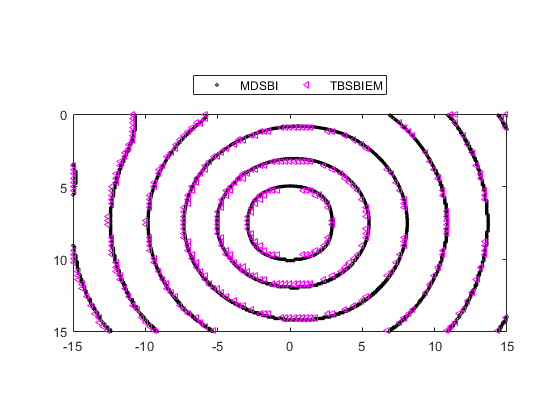

plot3(Results_020Sec.Var2,Results_020Sec.Var3,Results_020Sec.Var4,'m<',"MarkerSize",4)
plot3(Results_030Sec.Var2,Results_030Sec.Var3,Results_030Sec.Var4,'m<',"MarkerSize",4)
plot3(Results_040Sec.Var2,Results_040Sec.Var3,Results_040Sec.Var4,'m<',"MarkerSize",4)
plot3(Results_050Sec.Var2,Results_050Sec.Var3,Results_050Sec.Var4,'m<',"MarkerSize",4)
plot3(Results_060Sec.Var2,Results_060Sec.Var3,Results_060Sec.Var4,'m<',"MarkerSize",4)

axis equal
xlim([-15 15])
ylim([00 15])
zlim([0 0.4])
view(0,90)
legend([h1 h2],'MDSBI','TBSBIEM','Location','northoutside','NumColumns',4)
box on
set(gca,'Ydir','reverse')

saveas(figure(1),['Figs\TPV7_Contour_Plot.jpeg'])
saveas(figure(1),['Figs\TPV7_Contour_Plot.eps'],'epsc')